# Lab 1 by Cole Bardin     Section 61

## Bertalanffy Model of a Tumor

## Part A

## Question 1

clc, clear, close all
syms x C;
y = (75 + 25*x^2)/(1-x^4)

$$y = -\frac{25\,x^{2}+75}{x^{4}-1}$$

Y = int(y, x) + C

$$Y = C+25\,\mathrm{atan}\left(x\right)+50\,\mathrm{atanh}\left(x\right)$$


check = diff(Y,x)-y;
simplify(check)

$$ans = 0$$

## Questions 2-3

clc, clear, close all
syms y(t);
DE = diff(y,t) + 5*y == 13 + 15*t

$$DE(t) = \frac{\partial }{\partial t}y\left(t\right)+5\,y\left(t\right)=15\,t+13$$


sol_gen = dsolve(DE)

$$sol\_gen = 3\,t+\frac{C_{1}\,{\mathrm{e}}^{-5\,t}}{5}+2$$


sol_spec = dsolve(DE, y(0)==0)

$$sol\_spec = 3\,t-2\,{\mathrm{e}}^{-5\,t}+2$$

## Questions 4-5

clc, clear, close all
a = 1; b = a/2;
syms V(t);
DE = diff(V,t) == a*(V^(2/3)) - b*V;

sol = dsolve(DE, V(0)==1);
sol = sol(1) % Parse out first real answer

$$sol = -{\left({\mathrm{e}}^{-\frac{t}{6}}-2\right)}^{3}$$

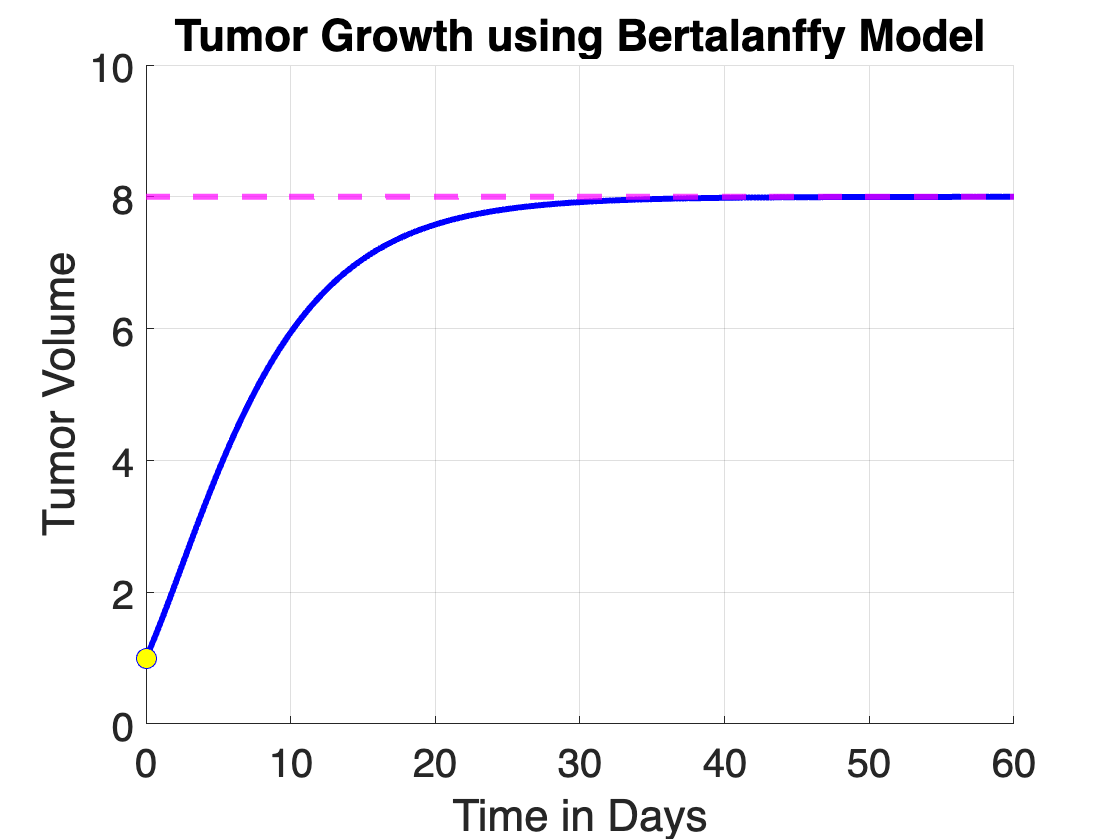


% Question 5
V = matlabFunction(sol);

figure('Name','Lab 1: Bertalanffy Model', 'NumberTitle','off');
Tmax = 60; % Plot the tumor for 60 days or about two months

hold on
x = 0:0.1:Tmax;
plot(x, V(x), 'b', 'LineWidth',3)
plot(0, V(0), 'bo', 'MarkerSize',10, 'MarkerFaceColor','y')
yline( (a/b)^3, 'm--', 'LineWidth',3 )

ax = gca; % current axes
ax.FontSize = 20;
% set(gca, 'fontsize', 20) % An alternative approach
% Customize the figure
grid on
axis([0 Tmax 0 10])

title("Tumor Growth using Bertalanffy Model")
ylabel("Tumor Volume")
xlabel("Time in Days")

## Part B

## Questions 6-7

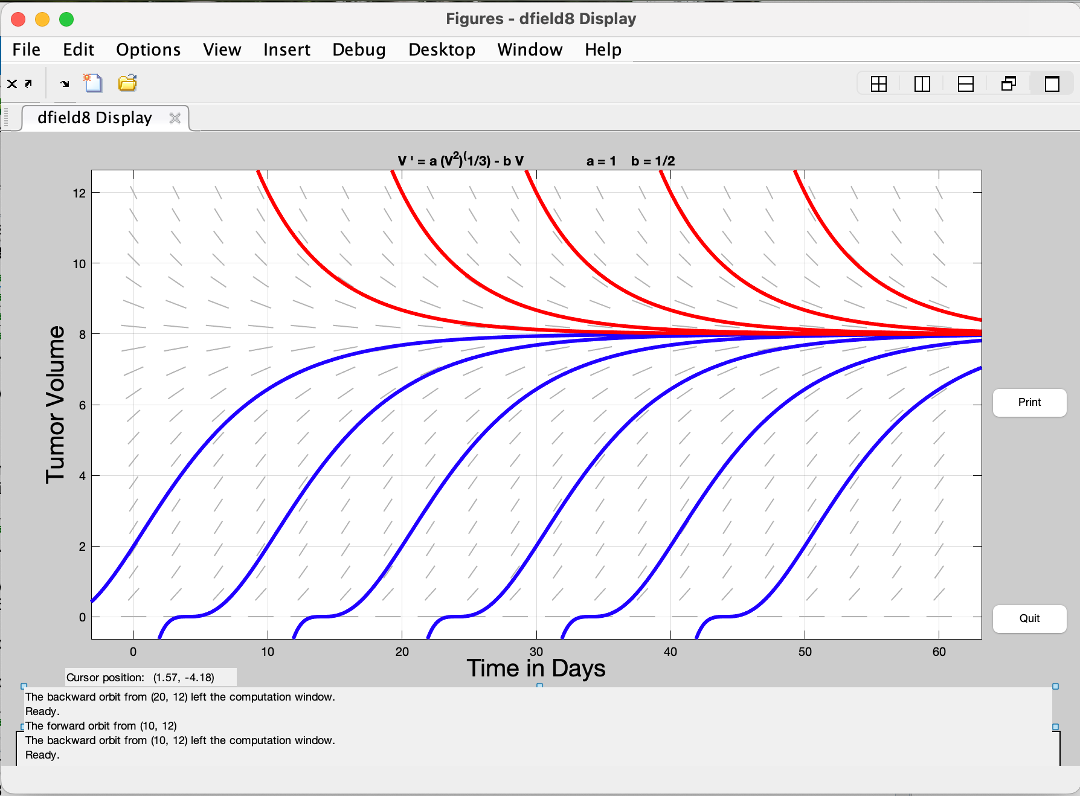

## Question 9

% Find at what volume the tumors are growing the fastest.
clear, clc
syms a b V
f = a * (V)^(2/3) - b * V ; % The RHS of the Bertalanffy DE.
% The tumors grow the fastest when f(V) is a maximum.
% That's when the derivative of f(V) wrt V is zero.
df = diff(f,V)

$$df = \frac{2\,a}{3\,V^{1/3}}-b$$

V_max_growth = solve(df, V)

$$V\_max\_growth = \frac{8\,a^{3}}{27\,b^{3}}$$

## Question 10

clear, clc
a = 1; b = a/2;
syms r(t) pi; % Be sure to make pi symbolic!
a1 = sym(a * (1/(36*pi))^(1/3)), b1 = sym(b/3)

$$a1 = {\left(\frac{1}{36\,\pi }\right)}^{1/3}$$

$$b1 = \frac{1}{6}$$

% Enter the linearized Bertalanffy DE here using a1, b1 and r.
DE = diff(r,t) == a1 - b1*r;
% Use dsolve to find the solution with r(0)==(3/(4*pi))^ (1/3)
rt = dsolve(DE, r(0)==(3/(4*pi))^ (1/3) )

$$rt = {\mathrm{e}}^{-\frac{t}{6}}\,\left({\left(\frac{3}{4\,\pi }\right)}^{1/3}-6\,{\left(\frac{1}{36\,\pi }\right)}^{1/3}\right)+6\,{\left(\frac{1}{36\,\pi }\right)}^{1/3}$$

% Compute and simplify V(t) using the formula for the volume of a sphere of radius r. 
Vt = simplify((4*pi/3)*(rt^3))

$$Vt = {\mathrm{e}}^{-\frac{t}{2}}\,{\left(2\,{\mathrm{e}}^{t/6}-1\right)}^{3}$$